% Show that series
% u(x,n)=x^n/2^(n-1)
% in the interval (-2;2) converges unevenly

clear
syms x n;
u(x,n)=x^n/2^(n-1)

$$u(x, n) = 2^{1-n}\,x^{n}$$


D(x,n)=simplify(u(x,n+1)/u(x,n))

$$D(x, n) = \frac{x}{2}$$

% x/2

% if x<2 => D<1 => series converges
% if x=2 => D=1 => series diverges

x=-2

x = -2

u1(n)=u(x,n)

$$u1(n) = 2^{1-n}\,{\left(-2\right)}^{n}$$

% 2^(1 - n)*(-2)^n
S=symsum(u(x,n),n,1,inf)

$$S = \mathrm{NaN}$$

% NaN

x=-1

x = -1

u1(n)=u(x,n)

$$u1(n) = {\left(-1\right)}^{n}\,2^{1-n}$$

% (-1)^n*2^(1 - n)
S=symsum(u(x,n),n,1,inf)

$$S = -\frac{2}{3}$$

% -2/3

x=1

x = 1

u1(n)=u(x,n)

$$u1(n) = 2^{1-n}$$

% 2^(1 - n)
S=symsum(u(x,n),n,1,inf)

$$S = 2$$

% 2

x=2

x = 2

u1(n)=u(x,n)

$$u1(n) = 2^{1-n}\,2^{n}$$

% 2^(1 - n)*2^n
S=symsum(u(x,n),n,1,inf)

$$S = \infty$$

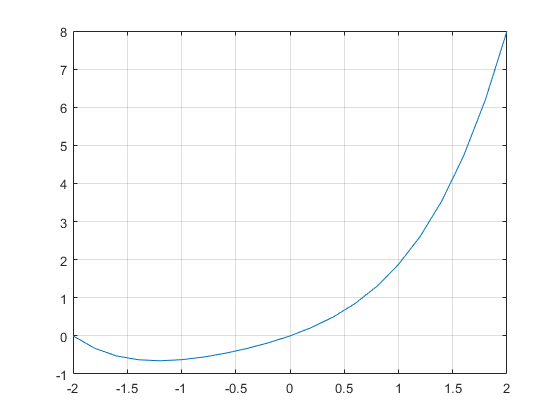

% Inf

syms i;
x1=-2:0.2:2;
s=zeros(1,length(x1));
for i=1:4
    s=s+u(x1,i);
    plot(x1,s)
    grid on
end
hold off